7.3

7.3(a)

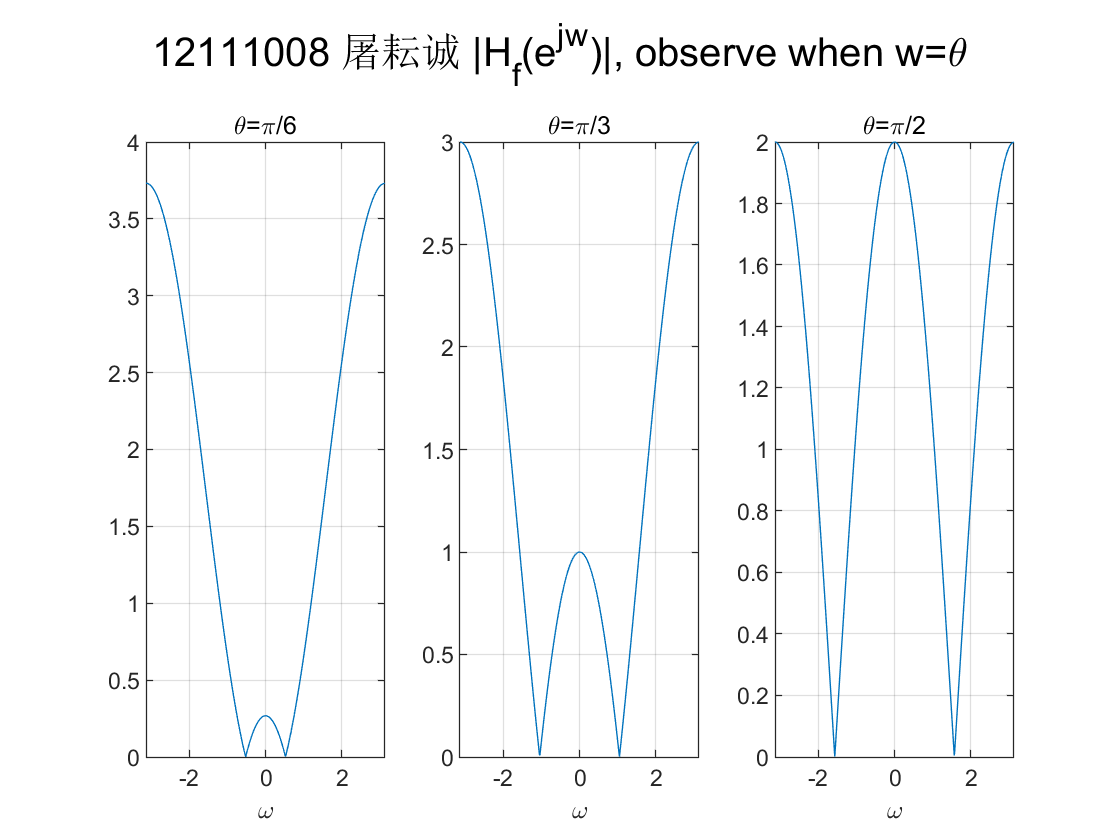


w = -pi:0.01:pi; z = exp(1j*w);
H1 = 1-2*cos(pi/6)*z.^(-1)+z.^(-2);
H2 = 1-2*cos(pi/3)*z.^(-1)+z.^(-2);
H3 = 1-2*cos(pi/2)*z.^(-1)+z.^(-2);
figure
sgtitle('12111008 屠耘诚 |H_f(e^j^w)|, observe when w=\theta')
subplot(1,3,1);plot(w,abs(H1));xlabel('\omega');grid on;title('\theta=\pi/6');
subplot(1,3,2);plot(w,abs(H2));xlabel('\omega');grid on;title('\theta=\pi/3');
subplot(1,3,3);plot(w,abs(H3));xlabel('\omega');grid on;title('\theta=\pi/2');

7.3(b)

load nspeech1;  % Load the audio signal
%sound(nspeech1); 

% Plot the time domain of original nspeech1 signal for 101 samples
y1 = nspeech1(100:200);

% Compute and plot the magnitude of the DTFT for 1001 samples
y2 = nspeech1(100:1100);
[X2,w2] = DTFT(y2,0);

% Apply FIR filter to the audio signal
filtered_nspeech1 = FIRfilter(nspeech1);

% Listen to the filtered signal
sound(filtered_nspeech1,8192);
test_wave=[filtered_nspeech1,zeros(1,length(filtered_nspeech1))]

test_wave =     0.5841    0.0013    0.0039    0.0036    0.0039    0.0040    0.0043    0.0045    0.0042    0.0045    0.0042    0.0040    0.0038    0.0036    0.0034    0.0035    0.0036    0.0032    0.0035    0.0033    0.0029    0.0029    0.0025    0.0023    0.0021    0.0019    0.0017    0.0013    0.0003    0.0003    0.0000   -0.0007    0.0001    0.0003    0.0008    0.0015    0.0019    0.0026    0.0029    0.0029    0.0032    0.0030    0.0026    0.0030    0.0025    0.0023    0.0022    0.0023    0.0023    0.0023


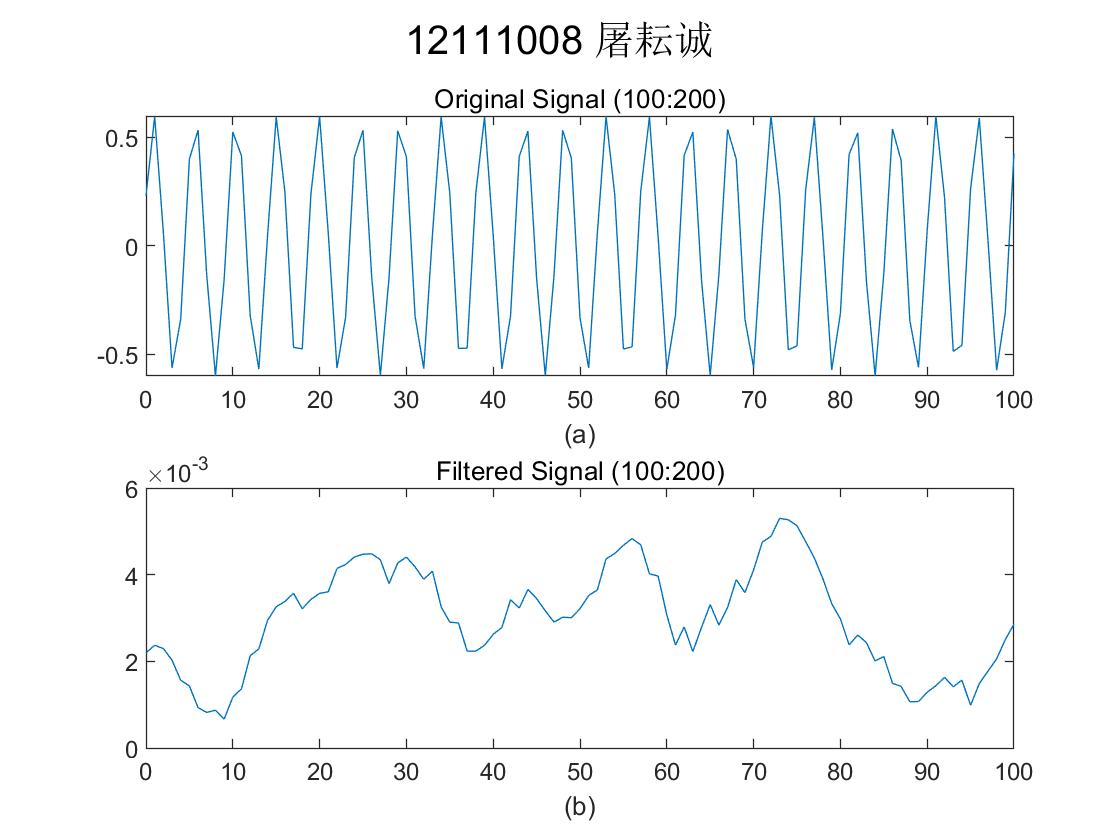

filename = ['filtered_nspeech1',  '.wav'];
audiowrite(filename,test_wave,8192);

y3 = filtered_nspeech1(100:200);
y4 = filtered_nspeech1(100:1100);

[Xmax,Imax] = max(abs(X2));
[X4,w4] = DTFT(y4,0);


figure;
sgtitle('12111008 屠耘诚');
subplot(211),plot([0:length(y1)-1],y1);xlabel('(a)');title('Original Signal (100:200)');
subplot(212),plot([0:length(y1)-1],y3);xlabel('(b)');title('Filtered Signal (100:200)');

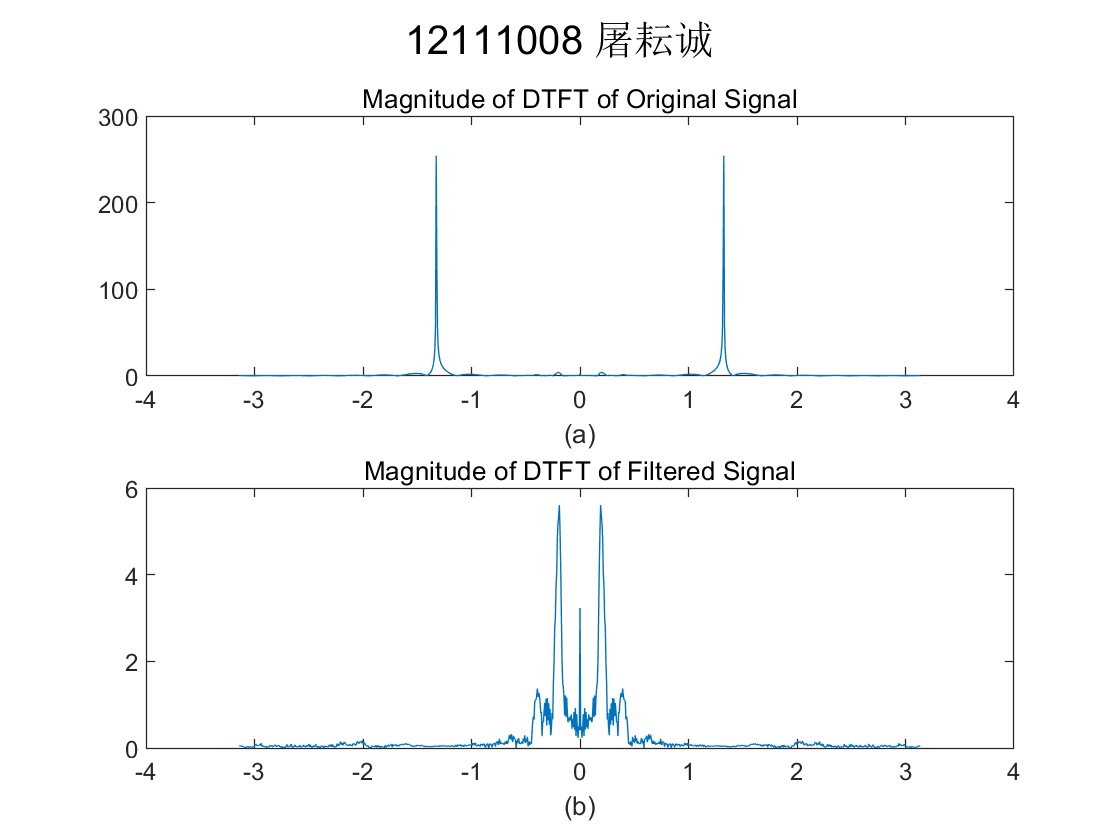

figure;sgtitle('12111008 屠耘诚');
subplot(211),plot(w2,abs(X2));xlabel('(a)');title('Magnitude of DTFT of Original Signal');

subplot(212),plot(w4,abs(X4));xlabel('(b)');title('Magnitude of DTFT of Filtered Signal');

7.4

7.4.1

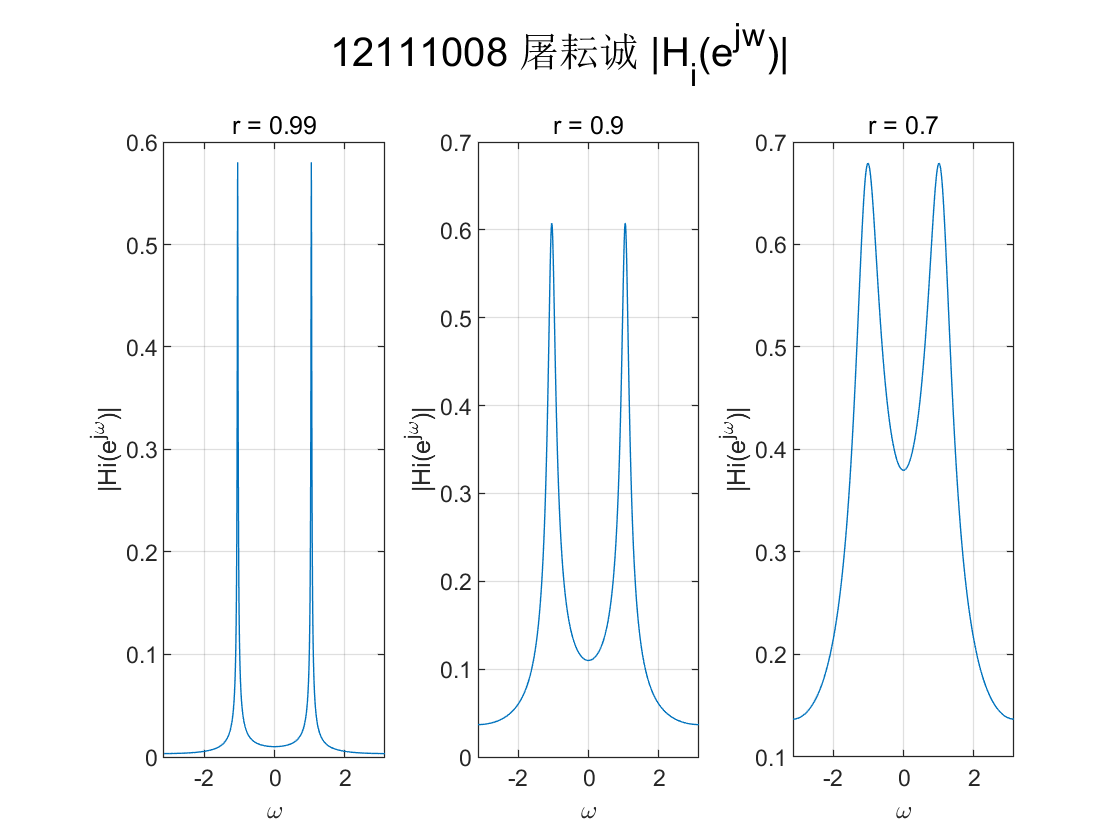



% Define the frequency range
omega = linspace(-pi, pi, 1000);

% Values of r and theta
rs = [0.99, 0.9, 0.7];
theta = pi/3;

% Plotting the magnitude response for each value of r
figure;
sgtitle('12111008 屠耘诚 |H_i(e^j^w)|')
for i = 1:length(rs)
    r = rs(i);
    H_i = abs((1 - r) ./ (1 - 2 * r * cos(theta) * exp(-1j * omega) + r^2 * exp(-2j * omega)));
    subplot(1,3,i)
    plot(omega, H_i);
    title(['r = ', num2str(r)]);
    xlabel('\omega');grid on;
    ylabel('|Hi(e^{j\omega})|');
    xlim([-pi pi]);
end

7.4.2

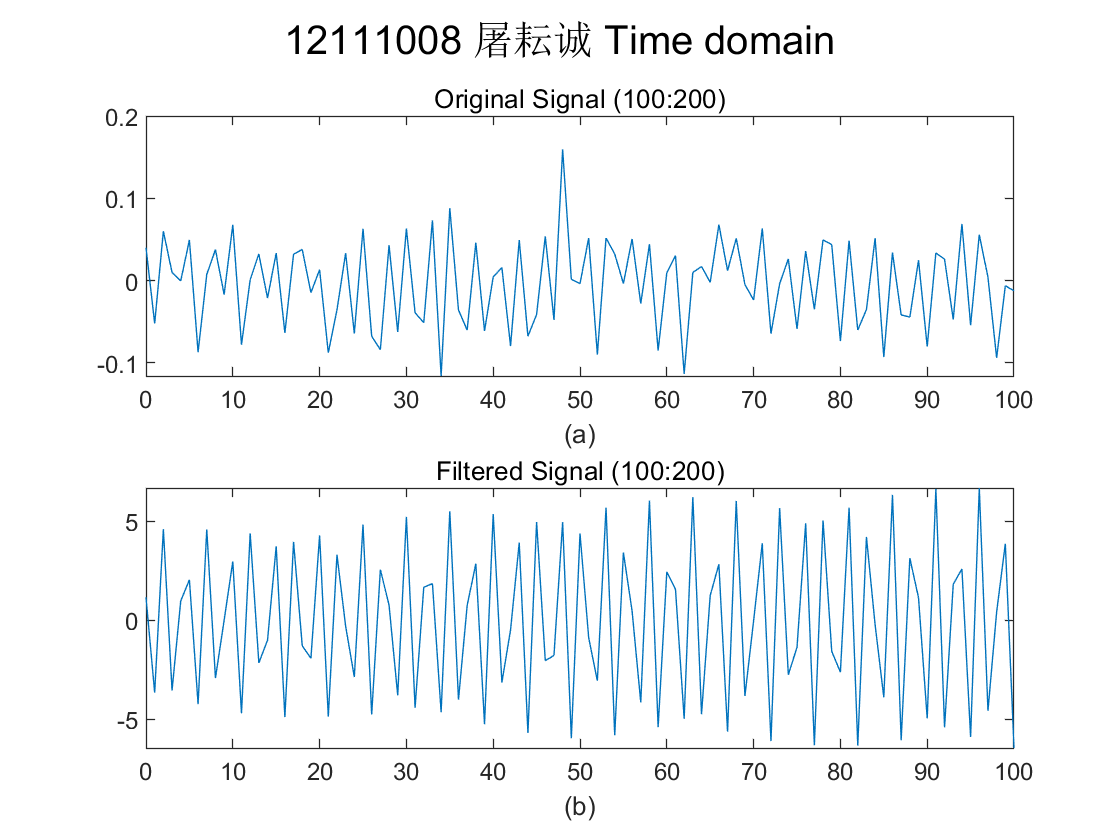


load pcm;
%sound(pcm); 
filtered_pcm = IIRfilter(pcm);
sound(filtered_pcm);
%time domain
pcm1 = pcm(100:200);
pcm1_filtered = filtered_pcm(100:200);
%frequency domain
pcm2 = pcm(100:1100);
[X,w] = DTFT(pcm2,0);
pcm2_filtered = filtered_pcm(100:1100);
[F,w] = DTFT(pcm2_filtered,0);


%θ
theta=(3146/8000)*2*pi;
w1 = w(w>(theta-0.02));
w1 = w1(w1<(theta+0.02));
X1 = X(w>(theta-0.02) & w<(theta+0.02));
f_X1 = F(w>(theta-0.02) & w<(theta+0.02));
figure
sgtitle('12111008 屠耘诚 Time domain');
subplot(211),plot(0:length(pcm1)-1,pcm1);xlabel('(a)');title('Original Signal (100:200)');
subplot(212),plot(0:length(pcm1)-1,pcm1_filtered);xlabel('(b)');title('Filtered Signal (100:200)');

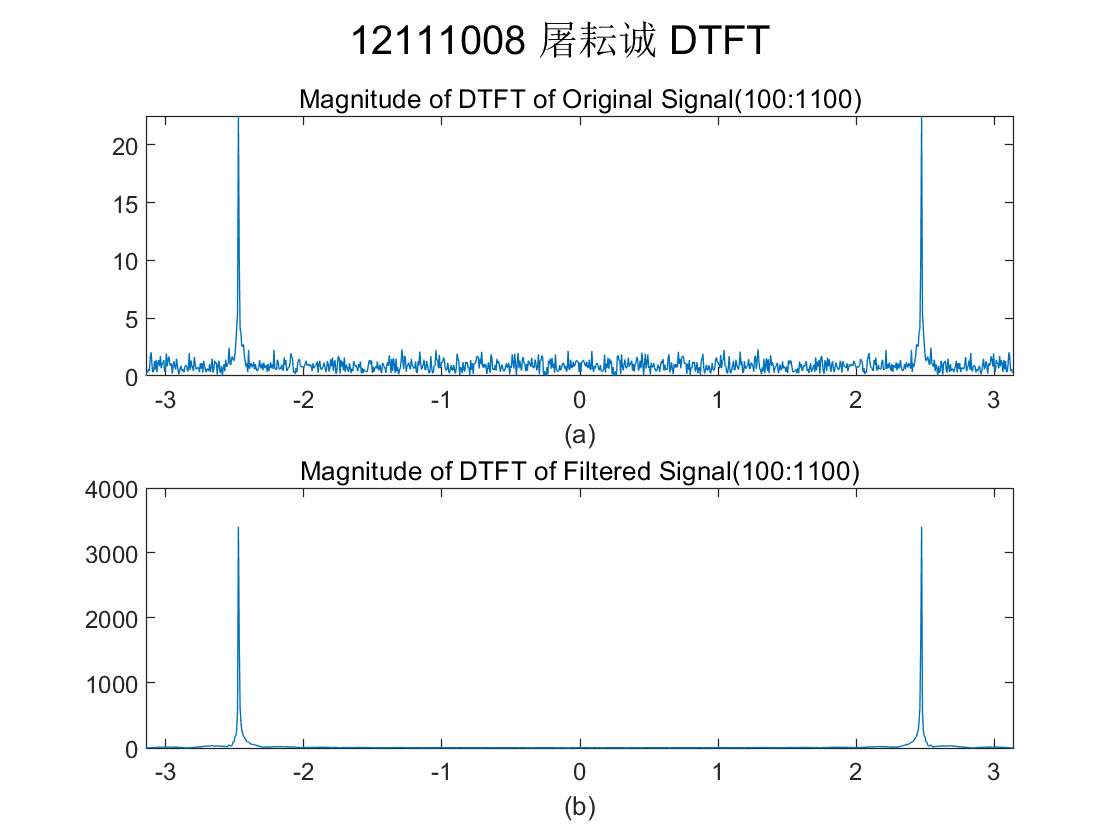


figure
sgtitle('12111008 屠耘诚 DTFT');
subplot(211),plot(w,abs(X));xlim([-pi pi]);xlabel('(a)');title('Magnitude of DTFT of Original Signal(100:1100)');
subplot(212),plot(w,abs(F));xlim([-pi pi]);xlabel('(b)');title('Magnitude of DTFT of Filtered Signal(100:1100)');

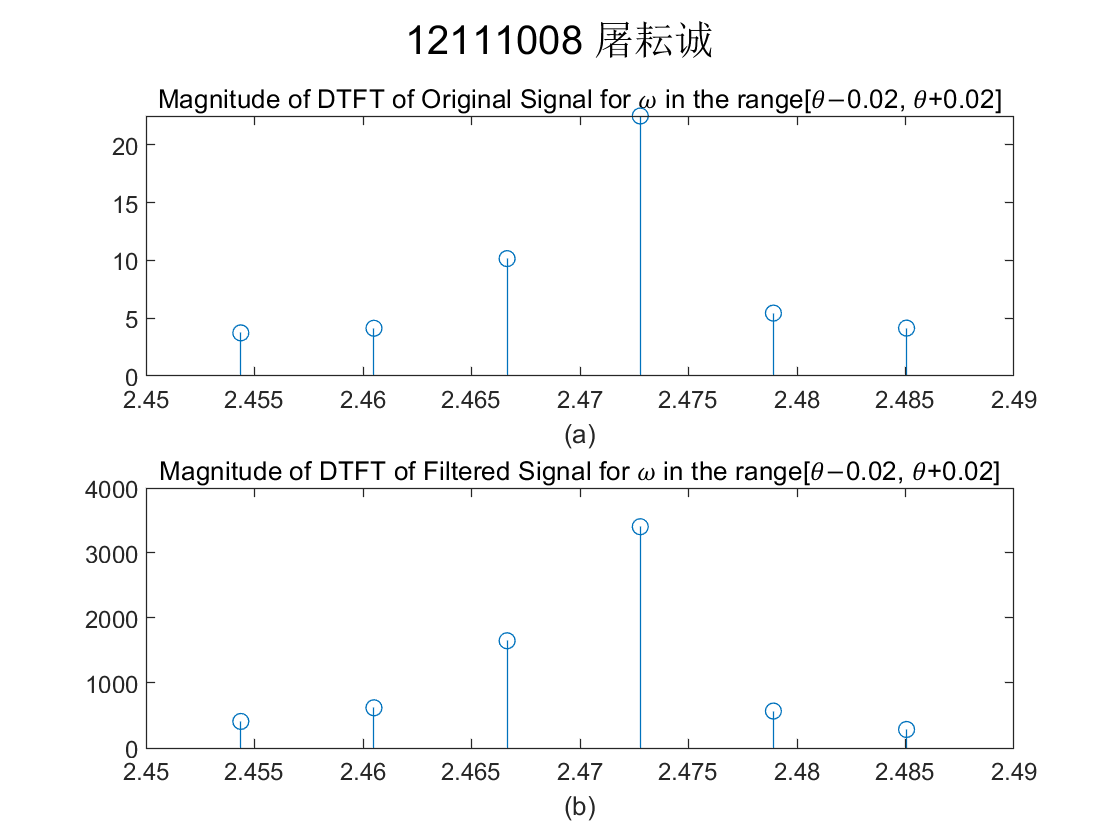


figure
sgtitle('12111008 屠耘诚');
subplot(211),stem(w1,abs(X1));xlabel('(a)');title('Magnitude of DTFT of Original Signal for 𝜔 in the range[𝜃−0.02, 𝜃+0.02]');
subplot(212),stem(w1,abs(f_X1));xlabel('(b)');title('Magnitude of DTFT of Filtered Signal for 𝜔 in the range[𝜃−0.02, 𝜃+0.02]');

7.6



load nspeech2.mat;
%sound(nspeech2)
N1=21;
N2=101;
h1 = LPFtrunc(N1);
[X1,w1] = DTFT(h1,512);
h2 = LPFtrunc(N2);
[X2,w2] = DTFT(h2,512);
%听音乐
y1=conv(nspeech2,LPFtrunc(21));
y2=conv(nspeech2,h2);
%sound(y1);
sound(y2);
test_wave=[y1]

test_wave =    -0.0000
    0.0000
   -0.0001
    0.0001
   -0.0001
    0.0000
    0.0001
   -0.0003
    0.0005
   -0.0006


filename = ['y1',  '.wav'];
audiowrite(filename,test_wave,8192);
test_wave=[y2]

test_wave =     0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


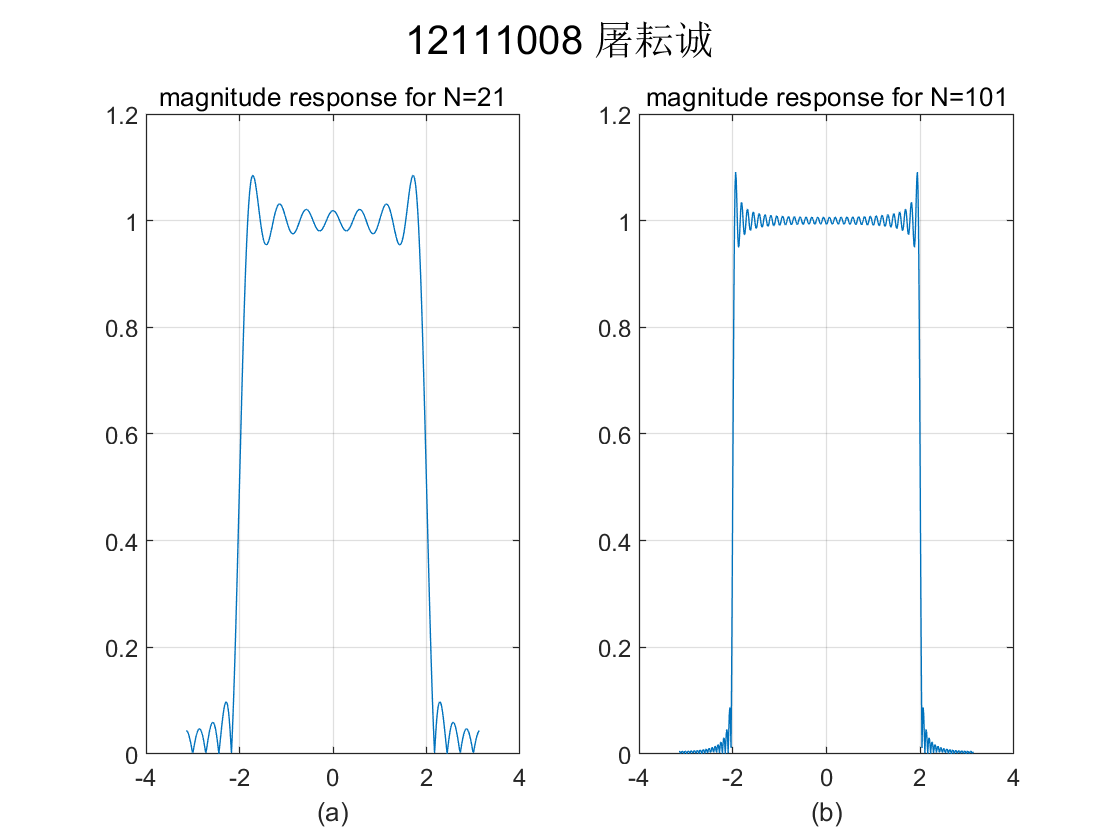

filename = ['y2',  '.wav'];
audiowrite(filename,test_wave,8192);
figure();
sgtitle('12111008 屠耘诚')
subplot(121),plot(w1,abs(X1));xlabel('(a)');grid on;title("magnitude response for N=21");
subplot(122),plot(w2,abs(X2));xlabel('(b)');grid on;title("magnitude response for N=101");

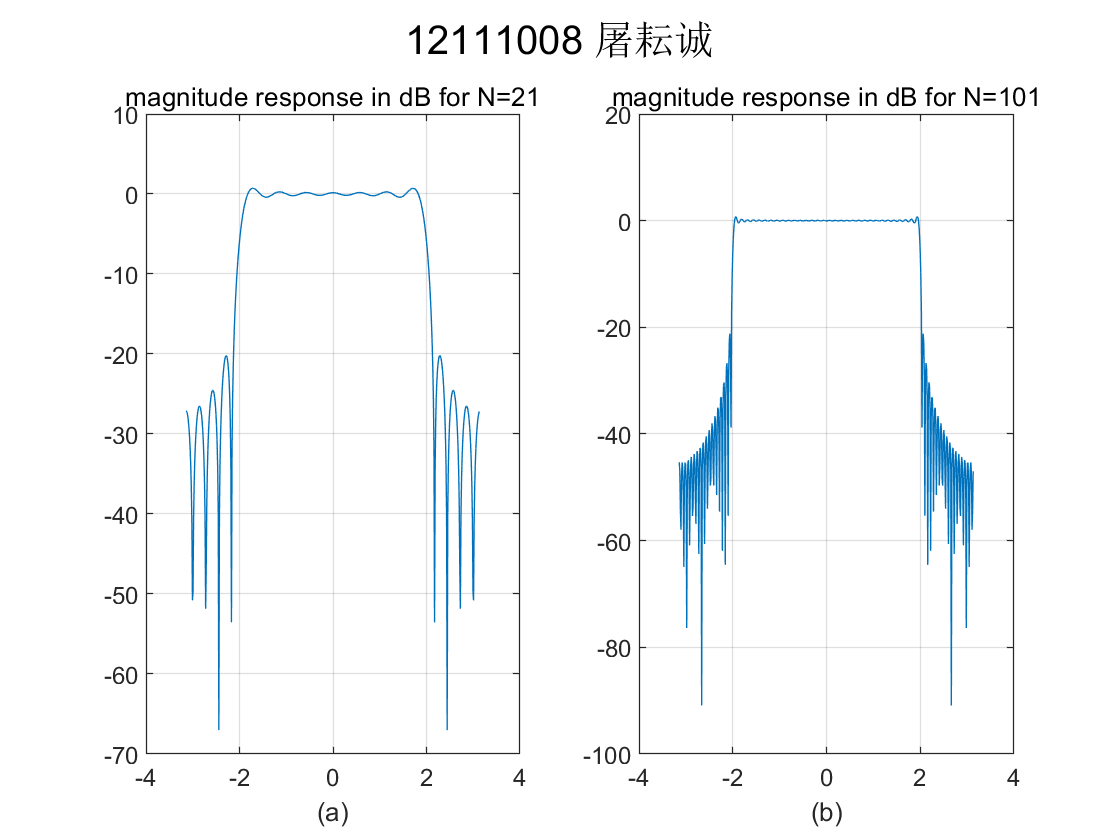

figure();
sgtitle('12111008 屠耘诚')
subplot(121),plot(w1,20*log10(abs(X1)));xlabel('(a)');grid on;title("magnitude response in dB for N=21");
subplot(122),plot(w2,20*log10(abs(X2)));xlabel('(b)');grid on;title("magnitude response in dB for N=101");